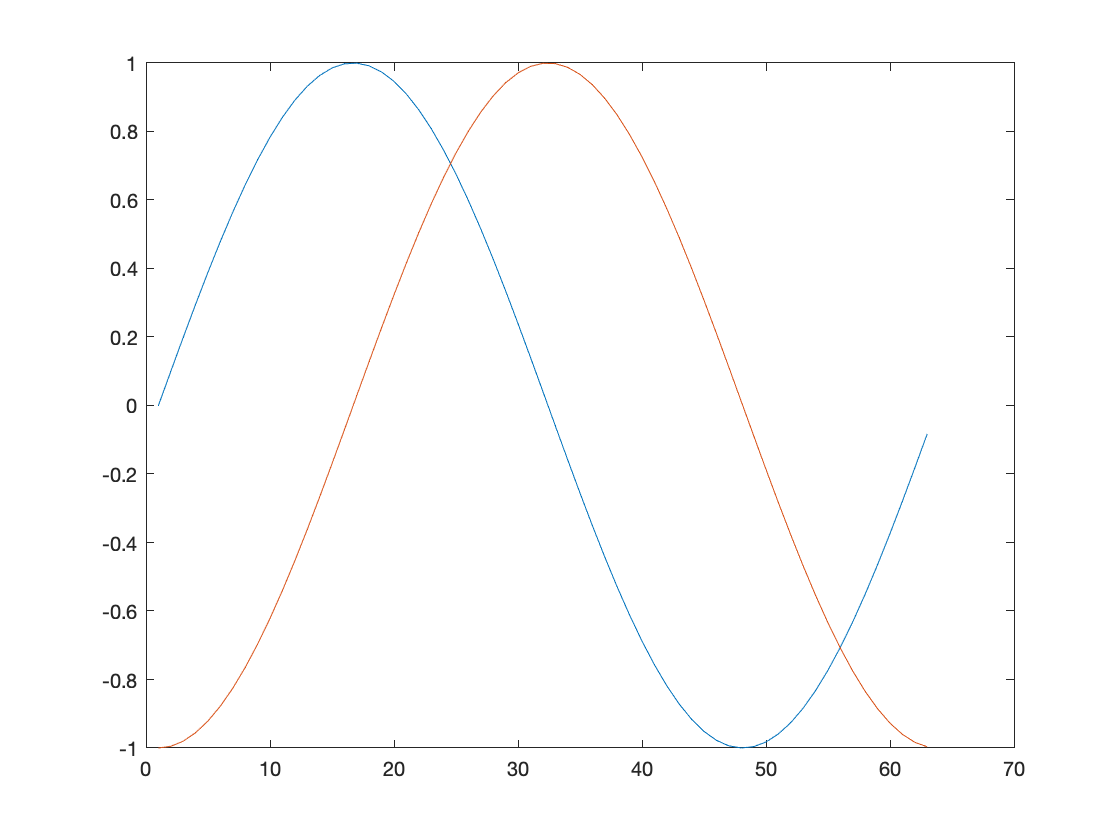

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% R.TRAPÉZIOS E R.SIMPSON RETORNAM A ÁREA
% Representar utilizando a função area ou int??

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



syms y(x)

s  =  "sin(x)";
a  =  0;
b  =  6.286;
n  =  20;

f = @(x) eval(vectorize(s));
d = int(f,x);
g = @(x) eval(vectorize(d));
x = a:h:b;
plot(f(x));
hold on;
plot(g(x));
hold on


n = (b-a)/n;

T = RTrapezios(f,a,b,n);
%tabela = [x.',y.',T.'];
disp(T);

    0.0281



%array2table(tabela,"VariableNames",{'x','y','dydx'})

out_S = RSimpson(f,a,b,n);
tabela = [x.',y.',out_S.'];

Unable to perform assignment because the size of the left side is 1-by-1 and the size of the right side is 63-by-1.

Error in sym/privsubsasgn (line 1128)
                L_tilde2 = builtin('subsasgn',L_tilde,struct('type','()','subs',{varargin}),R_tilde);

Error in sym/cat>catMany (line 42)
        y = privsubsasgn(y,arrays{k},subs{:});

Error in 

array2table(tabela,"VariableNames",{'x','y','dydx'})




[x,y,dydx] = DF2Progressivas(f,a,b,h);
tabela = [x.',y.',dydx.'];
array2table(tabela,"VariableNames",{'x','y','dydx'})

[x,y,dydx] = DF2Regressivas(f,a,b,h);
tabela = [x.',y.',dydx.'];
array2table(tabela,"VariableNames",{'x','y','dydx'})

[x,y,dydx] = DF3Progressivas(f,a,b,h);
tabela = [x.',y.',dydx.'];
array2table(tabela,"VariableNames",{'x','y','dydx'})

[x,y,dydx] = DF3Progressivas(f,a,b,h);
tabela = [x.',y.',dydx.'];
array2table(tabela,"VariableNames",{'x','y','dydx'})

[x,y,dydx] = DF3Centradas(f,a,b,h);
tabela = [x.',y.',dydx.'];
array2table(tabela,"VariableNames",{'x','y','dydx'})

[x,y,dydx] = DF3Derivada(f,a,b,h);
tabela = [x.',y.',dydx.'];
array2table(tabela,"VariableNames",{'x','y','dydx'})